clear ;
close all;

tic
load ryan3_gen_data.mat
toc 

Elapsed time is 1.753880 seconds.


# 변수 추출

cap = zeros();
Vd = zeros();
%Vd = [1:100];
battery_dataset(1).QDischargeSmooth

ans =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


battery_dataset(1).Vd

ans =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582   

size(battery_dataset(1).QDischargeSmooth)

ans =    428     1


length(battery_dataset(1).QDischargeSmooth)

ans = 428


idxAll = (1:length(battery_dataset));
idxTrainValid = [ idxTrain idxValid ];
idxTrainAll = []; %zeros();
idxValidAll = []; %zeros();
idxTestAll = []; %zeros();

j =1;
startIndx = j ;
GenerateFrameList = @(A,S,N) A+S*(0:N-1);

for i = 1: length(idxAll)
        
    cap_temp = battery_dataset(i).QDischargeSmooth;
    leng = length(cap_temp);
    %startIndx = j ;
    % https://kr.mathworks.com/matlabcentral/answers/478553-how-can-i-have-a-starting-number-a-step-size-then-the-number-of-numbers-i-need-in-a-1d-array
    append_index = GenerateFrameList(startIndx,1,leng);
    
    Vd_temp = battery_dataset(i).Vd ;
    Ic_temp = battery_dataset(i).Ic ;
    %Vd = [Vd ; Vd_temp];
    if  i == 1
        Vd = Vd_temp;
        cap = cap_temp; 
        Ic = Ic_temp;
    else
        Vd = vertcat(Vd,Vd_temp);
        cap = vertcat(cap,cap_temp);
        Ic = vertcat(Ic,Ic_temp);
    end
    
    if any(idxTrain(:) == i) 
       % https://kr.mathworks.com/matlabcentral/answers/283821-add-single-element-to-array-or-vector
       idxTrainAll =  [idxTrainAll append_index ] ;
    end
    if any(idxValid(:) == i) 
       idxValidAll =  [idxValidAll append_index ] ;
    end
    if any(idxTest(:) == i) 
       idxTestAll =  [idxTestAll append_index ] ;
    end
    %Vd(i) = Vd_temp;
    
    startIndx = startIndx + leng;
end
idxTrainAll

idxTrainAll =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idxValidAll

idxValidAll =         2793        2794        2795        2796        2797        2798        2799        2800        2801        2802        2803        2804        2805        2806        2807        2808        2809        2810        2811        2812        2813        2814        2815        2816        2817        2818        2819        2820        2821        2822        2823        2824        2825        2826        2827        2828        2829        2830        2831        2832        2833        2834        2835        2836        2837        2838        2839        2840        2841        2842


idxTestAll

idxTestAll =         4962        4963        4964        4965        4966        4967        4968        4969        4970        4971        4972        4973        4974        4975        4976        4977        4978        4979        4980        4981        4982        4983        4984        4985        4986        4987        4988        4989        4990        4991        4992        4993        4994        4995        4996        4997        4998        4999        5000        5001        5002        5003        5004        5005        5006        5007        5008        5009        5010        5011


cap

cap =     1.0479
    1.0478
    1.0477
    1.0476
    1.0475
    1.0474
    1.0473
    1.0472
    1.0471
    1.0470


Vd

Vd =     2.0166    3.2957    3.2329    3.2020    3.1854    3.1754    3.1689    3.1642    3.1605    3.1572    3.1545    3.1518    3.1495    3.1474    3.1452    3.1431    3.1411    3.1390    3.1368    3.1348    3.1327    3.1306    3.1286    3.1265    3.1243    3.1220    3.1199    3.1175    3.1152    3.1127    3.1103    3.1079    3.1052    3.1028    3.1002    3.0975    3.0949    3.0921    3.0895    3.0866    3.0838    3.0809    3.0780    3.0750    3.0719    3.0687    3.0654    3.0621    3.0585    3.0549
    2.0161    3.2949    3.2324    3.2014    3.1848    3.1749    3.1686    3.1637    3.1599    3.1568    3.1540    3.1515    3.1492    3.1469    3.1448    3.1427    3.1407    3.1386    3.1365    3.1345    3.1325    3.1304    3.1283    3.1262    3.1239    3.1217    3.1195    3.1171    3.1148    3.1125    3.1101    3.1076    3.1050    3.1025    3.0999    3.0972    3.0947    3.0919    3.0891    3.0863    3.0836    3.0806    3.0777    3.0747    3.0716    3.0684    3.0652    3.0619    3.0582    

Ic

Ic =          0    4.3998    4.4002    4.4002    4.4003    4.3998    4.3999    4.4003    4.4001    4.4003    4.4004    4.4003    4.3999    4.4002    4.3999    4.4000    4.3998    4.4001    4.4004    4.4000    4.3999    4.4004    4.3999    4.4001    4.3999    4.3999    4.3995    4.3998    4.3999    4.3999    4.4001    4.3999    4.4000    4.3996    4.4001    4.4001    4.3998    4.3993    4.4007    4.3997    4.3997    4.4000    4.4003    4.3997    4.4001    4.4001    4.4000    4.3999    4.4008    4.3999
         0    4.3998    4.3999    4.4002    4.3997    4.4004    4.3997    4.4002    4.4000    4.4005    4.4002    4.3999    4.3995    4.4000    4.4001    4.3998    4.3999    4.4000    4.4001    4.3999    4.4015    4.3998    4.4000    4.4002    4.3999    4.4002    4.4000    4.4000    4.4002    4.4003    4.4000    4.3999    4.4001    4.4003    4.4000    4.3998    4.3999    4.3996    4.4003    4.3989    4.4000    4.4002    4.4000    4.3998    4.4000    4.4000    4.3999    4.4001    4.4002    

% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))


Ic_org = Ic;
Ic_new = blockproc(Ic_org, blockSize, meanFilterFunction)

Ic_new =     3.5201    4.4001    4.4002    4.4001    4.4000    4.3998    4.3999    4.3999    4.3999    4.4001    4.4000    4.4000    4.3999    4.4000    2.9013    1.0000    1.0000    0.0994         0         0
    3.5199    4.4002    4.3999    4.3999    4.4003    4.4001    4.4001    4.3997    4.4000    4.4001    4.3999    4.4002    4.4000    4.2403    2.9039    1.0001    1.0000    0.0985         0         0
    3.5200    4.4000    4.3998    4.4000    4.3999    4.4000    4.4001    4.3999    4.4000    4.4000    4.3999    4.3999    4.3999    4.4000    2.8984    1.0000    1.0000    0.0986         0         0
    3.5198    4.4000    4.4000    4.4000    4.4001    4.4001    4.4000    4.3999    4.4000    4.4001    4.4001    4.4000    4.4002    4.1381    2.8975    0.9998    0.9999    0.0946         0         0
    3.5200    4.4001    4.4001    4.4000    4.4001    4.3999    4.4000    4.4000    4.4000    4.4000    4.3996    4.4000    4.3997    4.3998    2.8970    0.9998    1.0000    0.0949       

clear Ic Ic_org Ic_temp
Vd_org = Vd;
Vd_new = blockproc(Vd_org, blockSize, meanFilterFunction)

Vd_new =     2.9865    3.1652    3.1497    3.1389    3.1285    3.1174    3.1053    3.0921    3.0779    3.0619    3.0428    3.0185    2.9853    2.9360    2.8528    2.6893    2.2963    1.9998    1.9998    1.9998
    2.9859    3.1648    3.1493    3.1386    3.1282    3.1171    3.1050    3.0918    3.0776    3.0616    3.0425    3.0182    2.9851    2.9357    2.8525    2.6892    2.2980    1.9999    1.9999    1.9999
    2.9866    3.1656    3.1499    3.1392    3.1287    3.1175    3.1054    3.0922    3.0779    3.0619    3.0428    3.0184    2.9853    2.9359    2.8522    2.6877    2.2909    2.0001    2.0001    2.0001
    2.9862    3.1650    3.1495    3.1388    3.1283    3.1172    3.1051    3.0919    3.0776    3.0617    3.0425    3.0182    2.9850    2.9355    2.8519    2.6878    2.2935    1.9997    1.9996    1.9996
    2.9862    3.1649    3.1494    3.1387    3.1283    3.1173    3.1051    3.0919    3.0778    3.0618    3.0426    3.0183    2.9851    2.9357    2.8521    2.6878    2.2933    2.0001    2.0

clear Vd Vd_org Vd_temp

x = Vd_new;
%x = Ic_new;
y = cap;
[ynorm,ymax,ymin,yrate,xnorm,xmax,xmin,xrate] = minmax_norm_new(y,x);
clear Ic_new Vd_new
clear battery_dataset

# 학습/검증 및 테스트 데이타 추출

x_trainValid = xnorm([idxTrainAll idxValidAll],:)

x_trainValid =     0.7824    0.9237    0.9115    0.9030    0.8947    0.8860    0.8763    0.8659    0.8547    0.8420    0.8269    0.8077    0.7815    0.7425    0.6766    0.5473    0.2364    0.0019    0.0019    0.0019
    0.7819    0.9234    0.9111    0.9027    0.8945    0.8857    0.8761    0.8657    0.8545    0.8418    0.8267    0.8074    0.7813    0.7422    0.6764    0.5472    0.2378    0.0020    0.0020    0.0020
    0.7824    0.9240    0.9117    0.9032    0.8949    0.8860    0.8764    0.8660    0.8547    0.8420    0.8269    0.8076    0.7814    0.7423    0.6762    0.5460    0.2321    0.0021    0.0021    0.0021
    0.7821    0.9236    0.9113    0.9029    0.8946    0.8858    0.8762    0.8658    0.8545    0.8419    0.8267    0.8074    0.7812    0.7421    0.6759    0.5461    0.2342    0.0018    0.0017    0.0017
    0.7821    0.9235    0.9112    0.9028    0.8946    0.8858    0.8762    0.8658    0.8546    0.8419    0.8268    0.8075    0.7813    0.7422    0.6761    0.5461    0.2341    0.0022 

x_test = xnorm([idxTestAll],:)

x_test =     0.7864    0.9287    0.9163    0.9078    0.8995    0.8906    0.8808    0.8702    0.8589    0.8461    0.8309    0.8113    0.7844    0.7436    0.6730    0.5304    0.1902    0.0018    0.0019    0.0019
    0.7861    0.9284    0.9160    0.9074    0.8990    0.8902    0.8804    0.8699    0.8585    0.8457    0.8303    0.8107    0.7837    0.7426    0.6716    0.5277    0.1846    0.0020    0.0020    0.0020
    0.7860    0.9281    0.9158    0.9072    0.8988    0.8900    0.8803    0.8697    0.8582    0.8455    0.8300    0.8105    0.7834    0.7422    0.6710    0.5268    0.1848    0.0017    0.0017    0.0017
    0.7863    0.9285    0.9161    0.9075    0.8991    0.8902    0.8805    0.8698    0.8584    0.8457    0.8303    0.8106    0.7835    0.7424    0.6708    0.5260    0.1824    0.0020    0.0020    0.0020
    0.7865    0.9287    0.9162    0.9076    0.8993    0.8904    0.8806    0.8699    0.8585    0.8458    0.8304    0.8107    0.7836    0.7422    0.6706    0.5252    0.1807    0.0021    0.0


y_trainValid = ynorm([idxTrainAll idxValidAll])

y_trainValid =     0.9878
    0.9872
    0.9867
    0.9861
    0.9855
    0.9849
    0.9843
    0.9837
    0.9832
    0.9826


y_test = ynorm([idxTestAll])

y_test =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


# 선형회귀

tic
mdl = fitlm(x_trainValid,y_trainValid)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate       SE         tStat        pValue   
                   ________    _________    ________    ___________

    (Intercept)      10.239     0.088837      115.25              0
    x1             -0.10856    0.0049403     -21.974    2.3179e-106
    x2               -22.24       1.0035     -22.163    3.7201e-108
    x3               48.594       2.4353      19.954     3.8751e-88
    x4              -32.415       2.5192     -12.867     8.2431e-38
    x5              -4.4517       2.3201     -1.9188       0.055019
    x6              -26

toc

Elapsed time is 2.994072 seconds.



coeff = mdl.Coefficients.Estimate

coeff =    10.2386
   -0.1086
  -22.2405
   48.5941
  -32.4147
   -4.4517
  -26.9626
    5.6155
   -2.0151
   17.8124


x_trainValid(1,:)

ans =     0.7824    0.9237    0.9115    0.9030    0.8947    0.8860    0.8763    0.8659    0.8547    0.8420    0.8269    0.8077    0.7815    0.7425    0.6766    0.5473    0.2364    0.0019    0.0019    0.0019


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat = x_trainValid*coeff(2:21)+coeff(1)

yhat =     1.0262
    1.0300
    1.0195
    1.0233
    1.0256
    1.0265
    1.0241
    1.0268
    1.0216
    1.0205


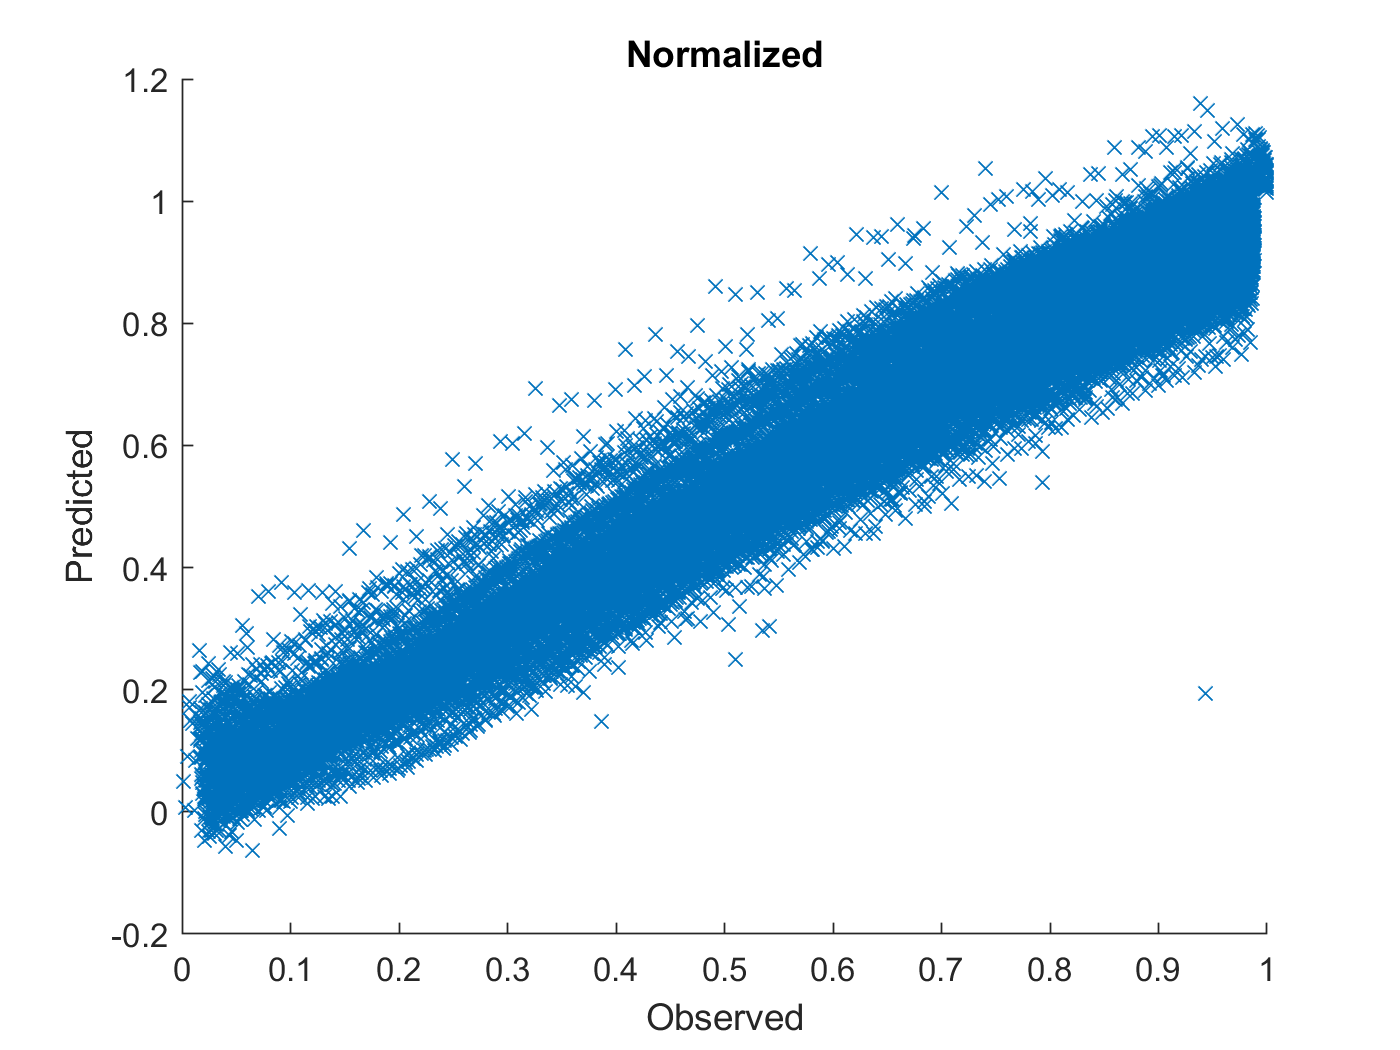

figure
hold on
plot(y_trainValid,yhat,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

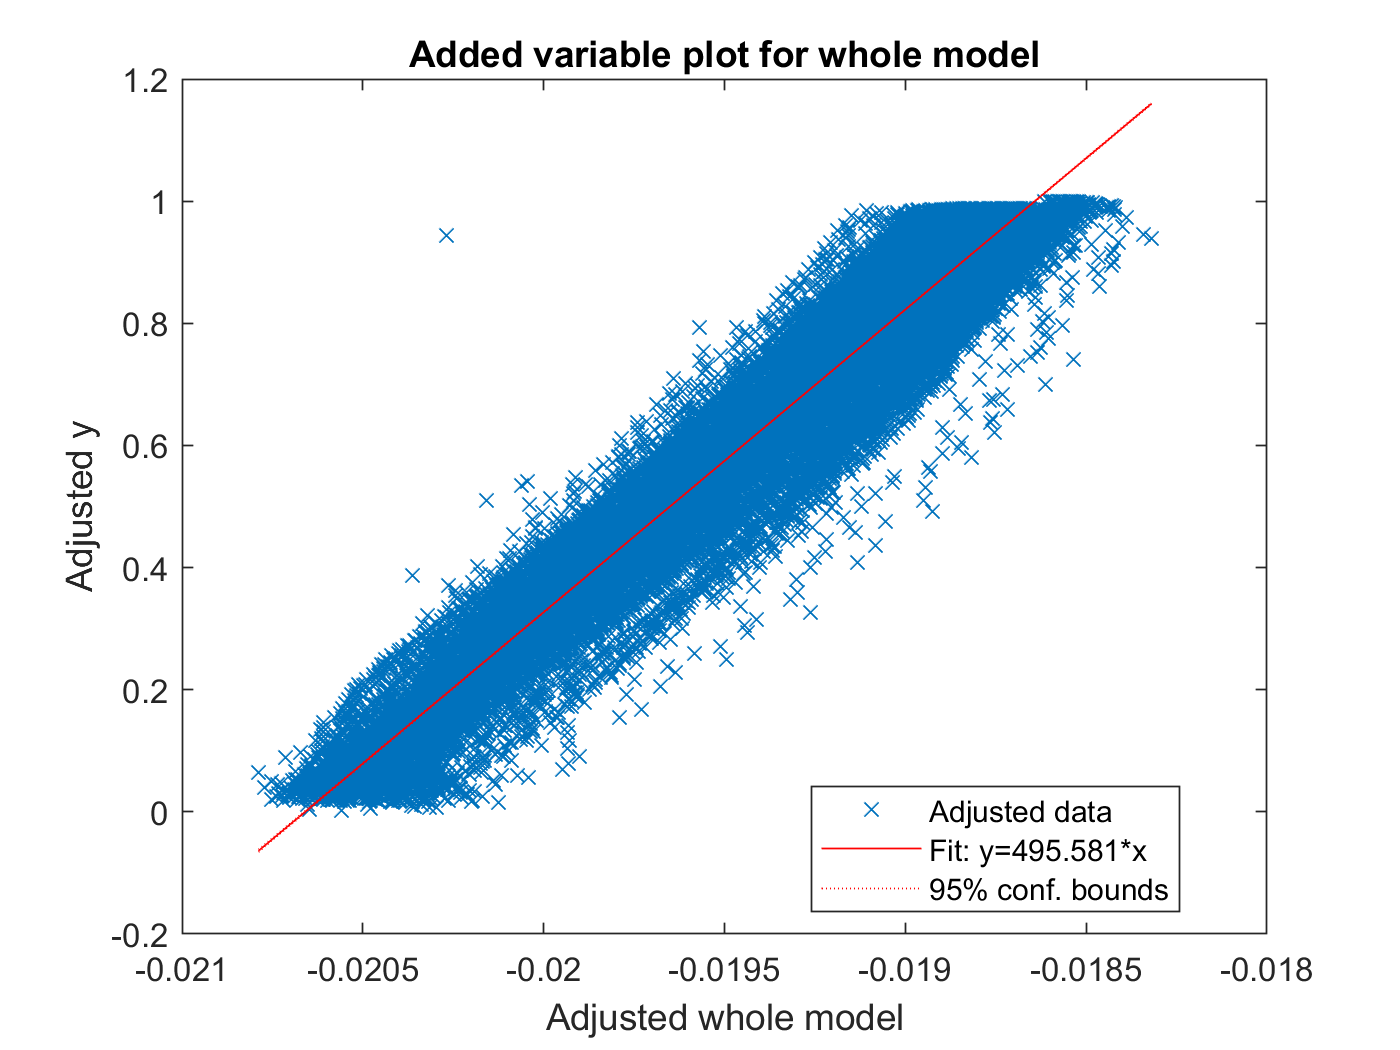


%capHat = Ic(1)

plot(mdl)

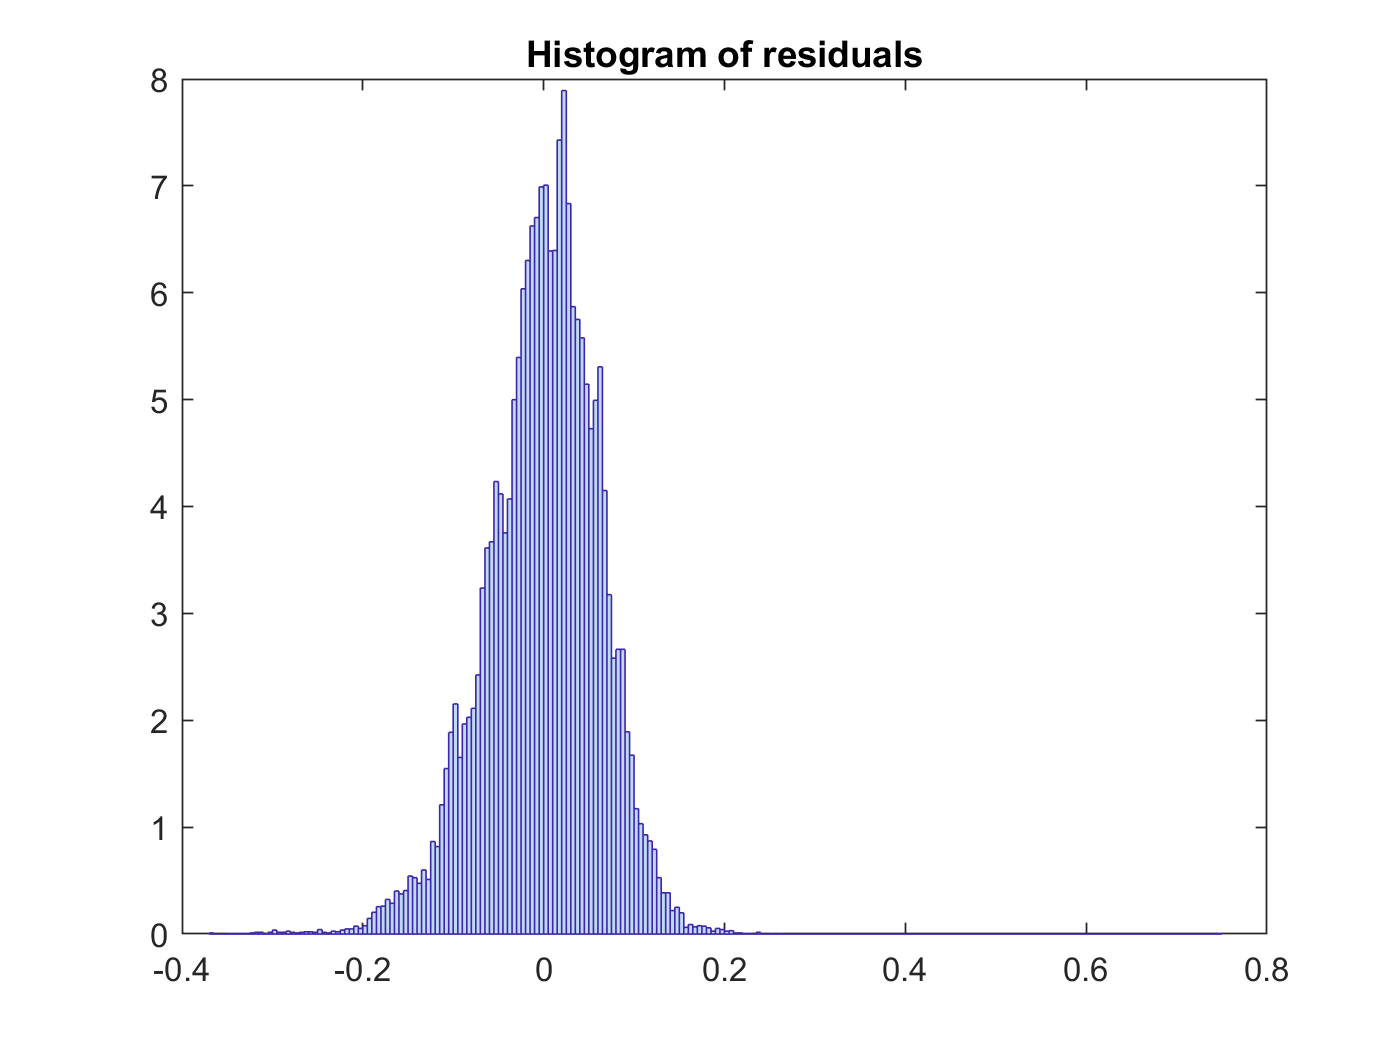

plotResiduals(mdl)




% yfit = predict(mdl,Ic)
yfit = predict(mdl,x_trainValid)

yfit =     1.0262
    1.0300
    1.0195
    1.0233
    1.0256
    1.0265
    1.0241
    1.0268
    1.0216
    1.0205


yfit_test = predict(mdl,x_test)

yfit_test =     0.9468
    0.9518
    0.9539
    0.9475
    0.9437
    0.9481
    0.9468
    0.9494
    0.9460
    0.9497




y= y_trainValid

y =     0.9878
    0.9872
    0.9867
    0.9861
    0.9855
    0.9849
    0.9843
    0.9837
    0.9832
    0.9826


y_test

y_test =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791



% denormalize
yfit = yfit * yrate + ymin;
y = y * yrate + ymin;
yfit_test = yfit_test * yrate + ymin;
y_test = y_test * yrate + ymin;


MAE = mean(abs(yfit-y))

MAE = 0.0084

adjMAE = MAE/range(y)

adjMAE = 0.0483

range(y) % y = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 0.1734


(y - yhat)    % Errors

ans =     0.0217
    0.0178
    0.0282
    0.0243
    0.0219
    0.0209
    0.0232
    0.0203
    0.0254
    0.0265


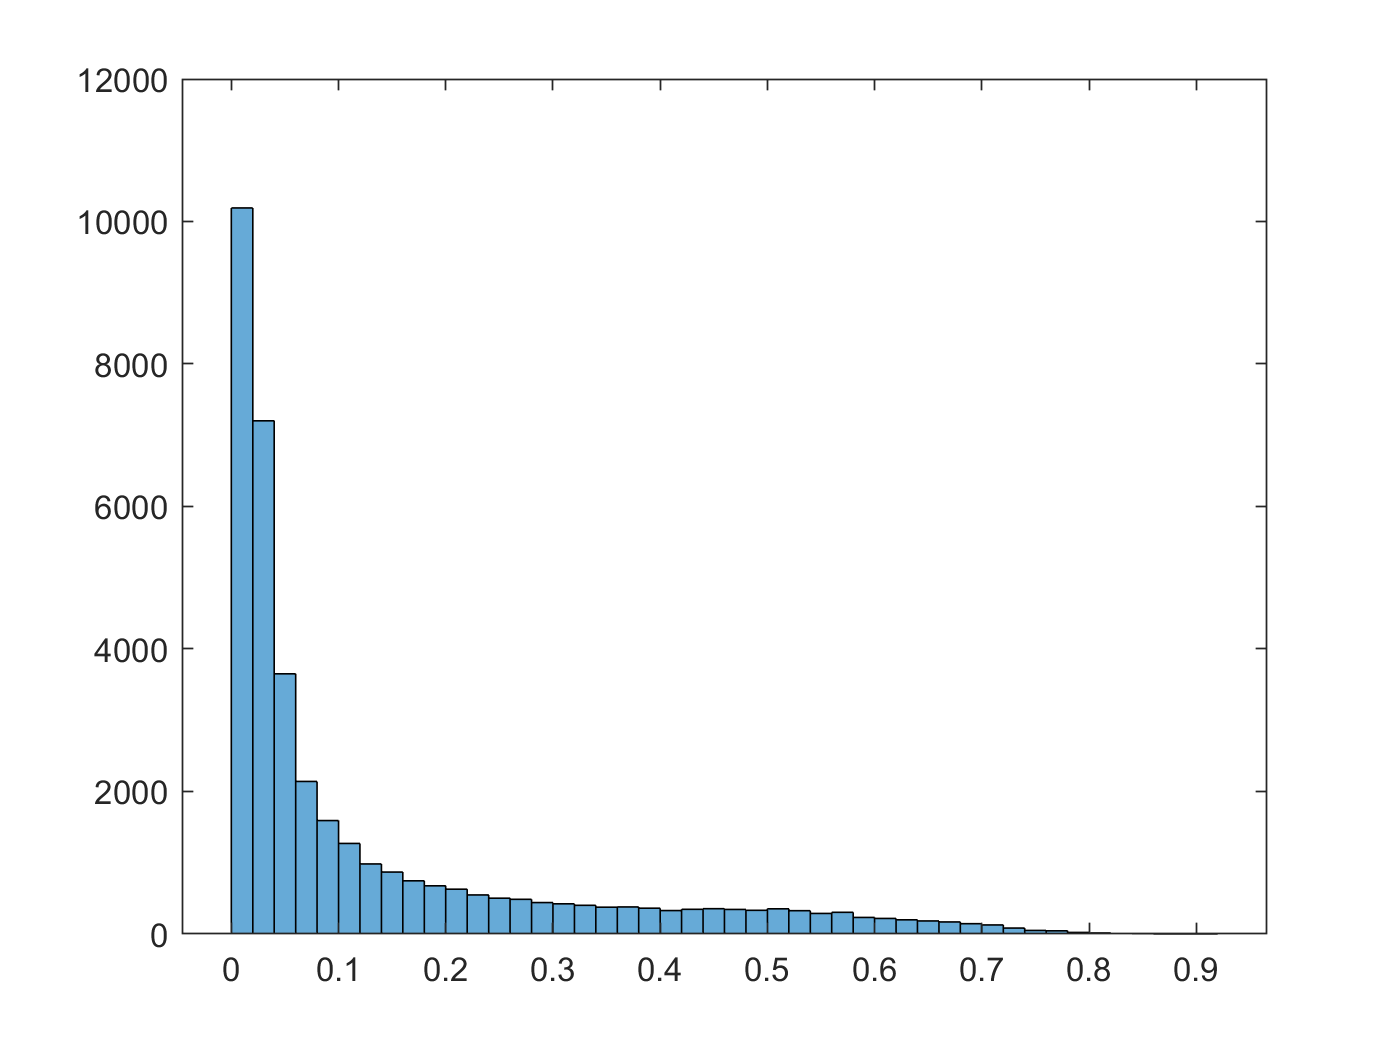

(y - yhat).^2;   % Squared Error
histogram((y - yhat).^2)

mean((y - yhat).^2);   % Mean Squared Error
RMSE = sqrt(mean((y - yhat).^2))  % Root Mean Squared Error

RMSE = 0.3682

(y_test - yfit_test) 

ans =     0.0070
    0.0060
    0.0054
    0.0064
    0.0069
    0.0060
    0.0061
    0.0055
    0.0059
    0.0051


RMSE_test = sqrt(mean((y_test - yfit_test).^2))

RMSE_test = 0.0120

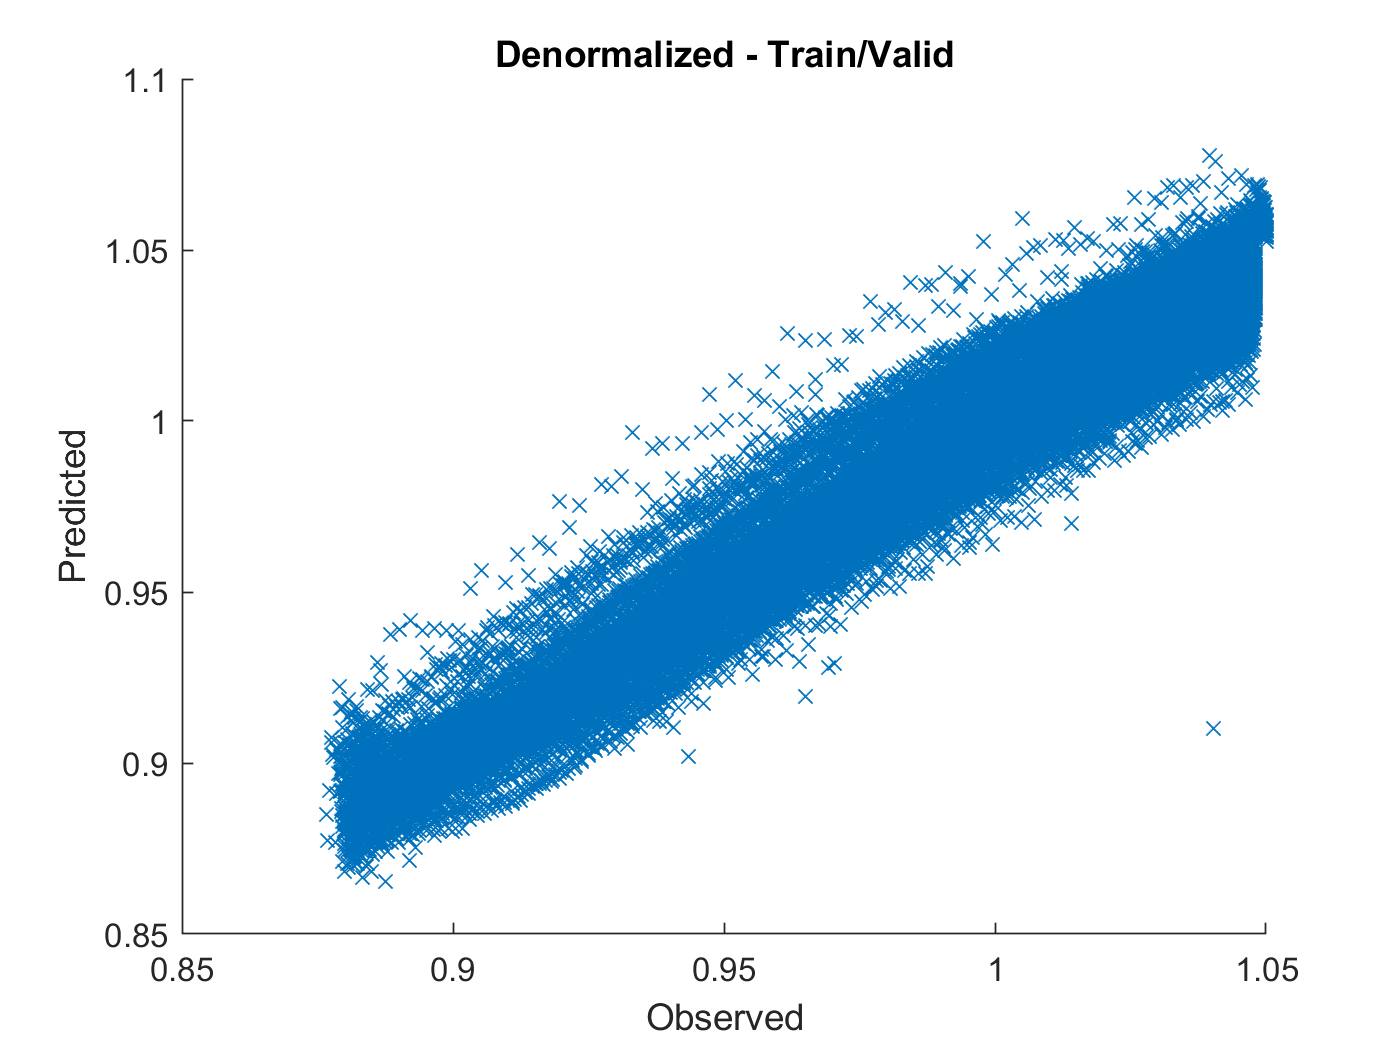


figure
hold on
plot(y,yfit,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Train/Valid'

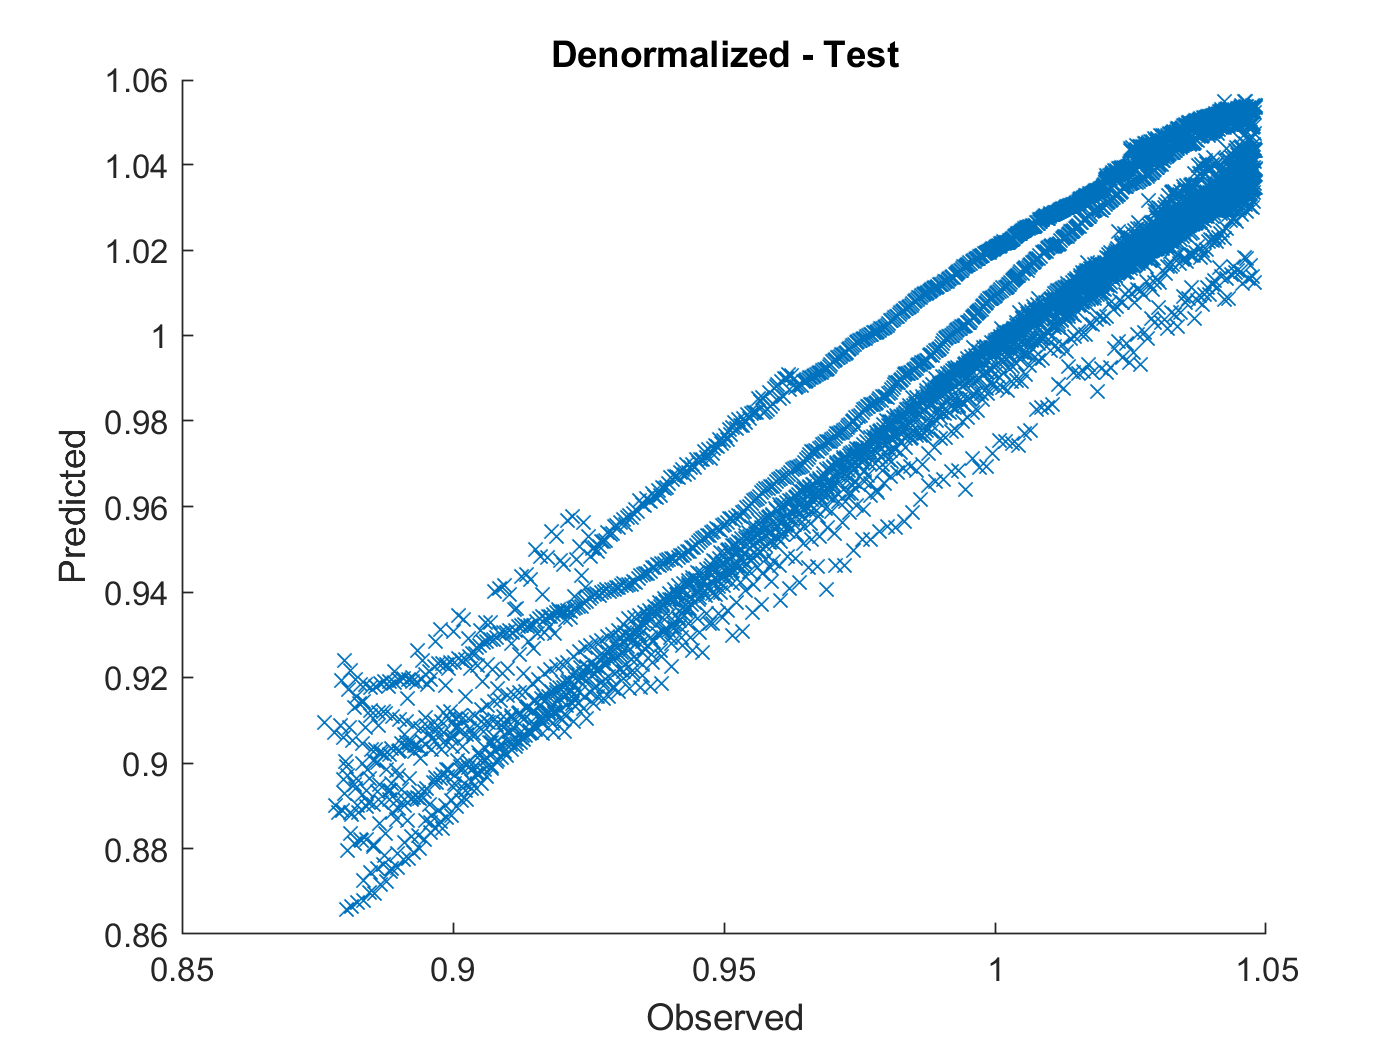


figure
hold on
plot(y_test,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Denormalized - Test'

%xlim([0 1200]), ylim([0 1200])

% 테스트 셋에서는 예측이 전혀 안된다.


# 머신러닝을 위한 기본 설정

epoc_count = 2;
cc_input_size = 20;



- FNN1 - 1 layer


netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainAll;
netFNN1_1.divideParam.valInd = idxValidAll;
netFNN1_1.divideParam.testInd = idxTestAll; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_1, tr] = train(netFNN1_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 0.762491 seconds.


%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';
netFNN1_2.divideParam.trainInd = idxTrainAll;
netFNN1_2.divideParam.valInd = idxValidAll;
netFNN1_2.divideParam.testInd = idxTestAll; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
netFNN1_2 = train(netFNN1_2, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 1.712197 seconds.


# FNN

netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';
netFNN1_3.divideParam.trainInd = idxTrainAll;
netFNN1_3.divideParam.valInd = idxValidAll;
netFNN1_3.divideParam.testInd = idxTestAll; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = epoc_count; % 전체 데이타를 300번 반복 이용해라
tic
[netFNN1_3, tr] = train(netFNN1_3, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 53.422574 seconds.



netFNN2_1 = feedforwardnet([20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
tic
[netFNN2_1, tr2] = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 4.173883 seconds.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([50,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
tic
netFNN2_2 = train(netFNN2_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 4.588994 seconds.


%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([50,20,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
tic
netFNN3_1 = train(netFNN3_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 59.047437 seconds.


%view(netFNN3_1)

netFNN4_1 = feedforwardnet([50,20,10,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
tic
netFNN4_1 = train(netFNN4_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 100.838389 seconds.


%view(netFNN3_1)

netFNN5_1 = feedforwardnet([50,20,10,5,5]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = epoc_count; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
tic
netFNN5_1 = train(netFNN5_1, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


toc

Elapsed time is 40.729170 seconds.


%view(netFNN3_1)

pFNN1_1 = netFNN1_1(xnorm(tr.testInd, :)');
pFNN1_2 = netFNN1_2(xnorm(tr.testInd, :)');
pFNN1_3 = netFNN1_3(xnorm(tr.testInd, :)');
pFNN2_1 = netFNN2_1(xnorm(tr.testInd, :)');
pFNN2_2 = netFNN2_2(xnorm(tr.testInd, :)');
pFNN3_1 = netFNN3_1(xnorm(tr.testInd, :)');
pFNN4_1 = netFNN4_1(xnorm(tr.testInd, :)');
pFNN5_1 = netFNN5_1(xnorm(tr.testInd, :)');

ytest = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_1_hat = pFNN1_1 * yrate + ymin;
pFNN1_2_hat = pFNN1_2 * yrate + ymin;
pFNN1_3_hat = pFNN1_3 * yrate + ymin;
pFNN2_1_hat = pFNN2_1 * yrate + ymin;
pFNN2_2_hat = pFNN2_2 * yrate + ymin;
pFNN3_1_hat = pFNN3_1 * yrate + ymin;
pFNN4_1_hat = pFNN4_1 * yrate + ymin;
pFNN5_1_hat = pFNN5_1 * yrate + ymin;


rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

rmse_pFNN1_1_hat = 0.0401

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

rmse_pFNN1_2_hat = 0.0118

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

rmse_pFNN1_3_hat = 0.0170

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

rmse_pFNN2_1_hat = 0.0322

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

rmse_pFNN2_2_hat = 0.0133

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

rmse_pFNN3_1_hat = 0.0111

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

rmse_pFNN4_1_hat = 0.0104

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

rmse_pFNN5_1_hat = 0.0104

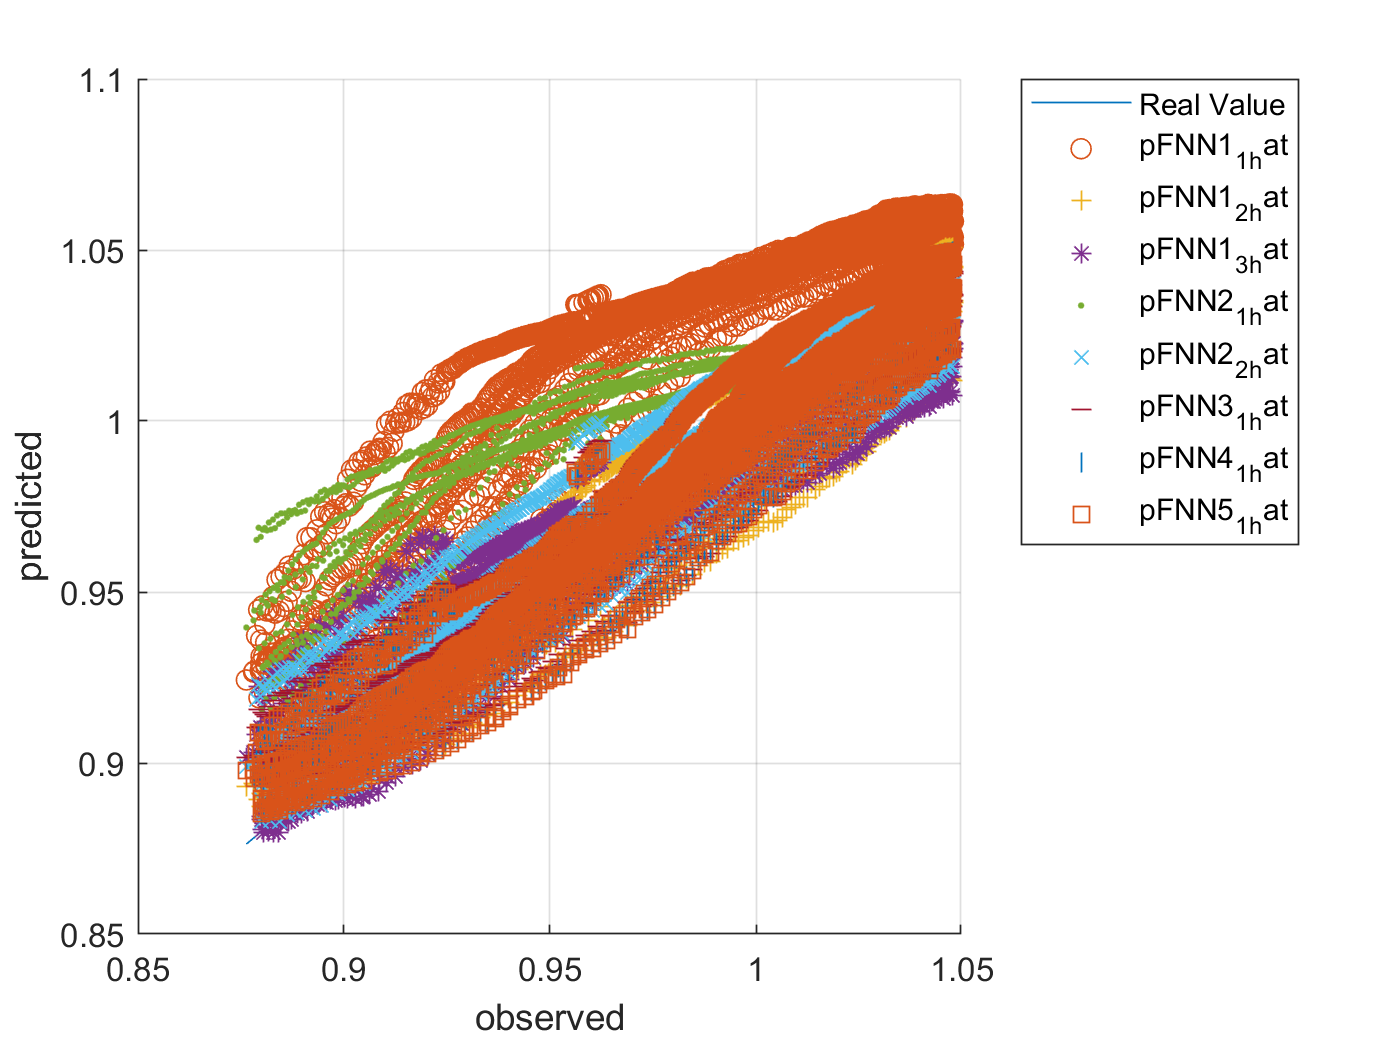


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

save('ryan3_model_dischargeVoltage_SOH.mat','netFNN1_1' )
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN1_2' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN1_3' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN2_1' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN2_2' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN3_1' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN4_1' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netFNN5_1' ,'-append')

pFNN1_1_self = netFNN1_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_2_self = netFNN1_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN1_3_self = netFNN1_3(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_1_self = netFNN2_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN2_2_self = netFNN2_2(xnorm([tr.trainInd tr.valInd], :)');
pFNN3_1_self = netFNN3_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN4_1_self = netFNN4_1(xnorm([tr.trainInd tr.valInd], :)');
pFNN5_1_self = netFNN5_1(xnorm([tr.trainInd tr.valInd], :)');

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pFNN1_1_self_hat = pFNN1_1_self * yrate + ymin;
pFNN1_2_self_hat = pFNN1_2_self * yrate + ymin;
pFNN1_3_self_hat = pFNN1_3_self * yrate + ymin;
pFNN2_1_self_hat = pFNN2_1_self * yrate + ymin;
pFNN2_2_self_hat = pFNN2_2_self * yrate + ymin;
pFNN3_1_self_hat = pFNN3_1_self * yrate + ymin;
pFNN4_1_self_hat = pFNN4_1_self * yrate + ymin;
pFNN5_1_self_hat = pFNN5_1_self * yrate + ymin;


rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

rmse_pFNN1_1_self_hat = 0.0395

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

rmse_pFNN1_2_self_hat = 0.0121

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

rmse_pFNN1_3_self_hat = 0.0173

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

rmse_pFNN2_1_self_hat = 0.0331

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

rmse_pFNN2_2_self_hat = 0.0131

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

rmse_pFNN3_1_self_hat = 0.0115

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

rmse_pFNN4_1_self_hat = 0.0110

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

rmse_pFNN5_1_self_hat = 0.0110

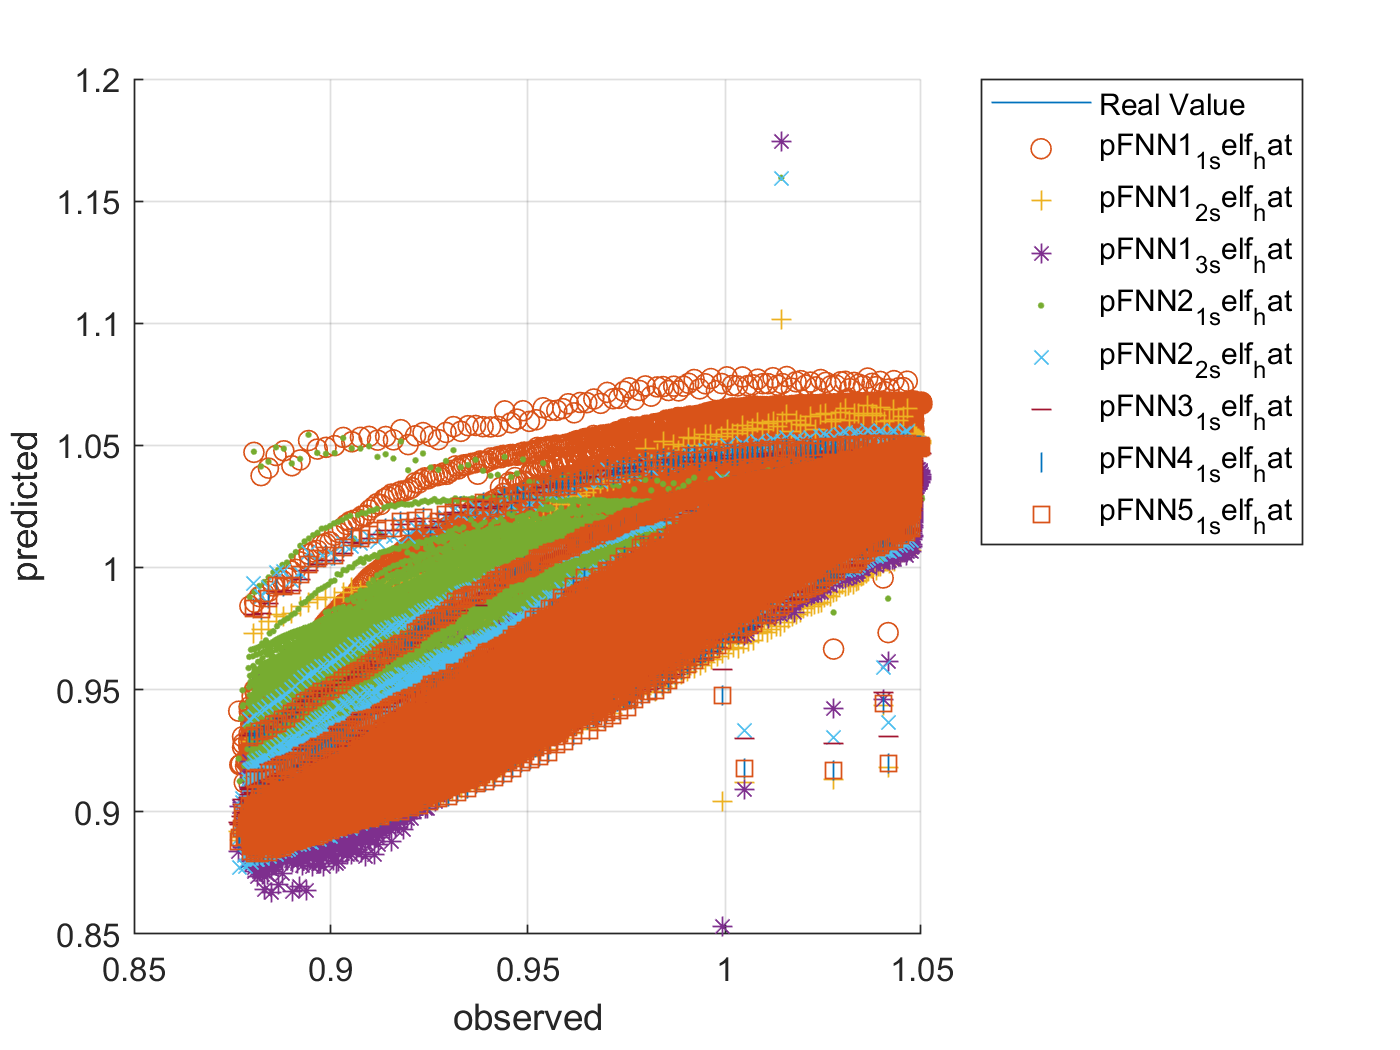



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN

% For CNN
filterSize = 3;
numFilters = 32;
numFCN = 1;



- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.



layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',epoc_count, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

tic
netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.62 |         0.61 |       0.1945 |       0.1884 |          0.0010 |
|       1 |          50 |       00:00:06 |         0.14 |         0.13 |       0.0097 |       0.0088 |          0.0010 |
|       1 |         100 |       00:00:08 |         0.10 |         0.10 |       0.0052 |       0.0048 |          0.0010 |
|       1 |         150 |       00:00:09 |         0.11 |         0.09 |       0.0061 |   

toc

Elapsed time is 62.310202 seconds.


- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

tic
netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.76 |         0.76 |       0.2893 |       0.2853 |          0.0010 |
|       1 |          50 |       00:00:09 |         0.20 |         0.18 |       0.0202 |       0.0155 |          0.0010 |
|       1 |         100 |       00:00:12 |         0.12 |         0.09 |       0.0068 |       0.0044 |          0.0010 |
|       1 |         150 |       00:00:15 |         0.08 |         0.09 |       0.0032 |   

toc

Elapsed time is 122.862652 seconds.






layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
tic
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:06 |         0.76 |         0.75 |       0.2920 |       0.2841 |          0.0010 |
|       1 |          50 |       00:00:08 |         0.20 |         0.17 |       0.0193 |       0.0141 |          0.0010 |
|       1 |         100 |       00:00:11 |         0.09 |         0.11 |       0.0043 |       0.0056 |          0.0010 |
|       1 |         150 |       00:00:12 |         0.11 |         0.10 |       0.0055 |   

toc

Elapsed time is 99.076734 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |         1.28 |         0.85 |       0.8174 |       0.3598 |          0.0010 |
|       1 |          50 |       00:00:15 |         0.12 |         0.13 |       0.0070 |       0.0089 |          0.0010 |
|       1 |         100 |       00:00:43 |         0.11 |         0.11 |       0.0061 |       0.0061 |          0.0010 |
|       1 |         150 |       00:01:02 |         0.14 |         0.11 |       0.0101 |   

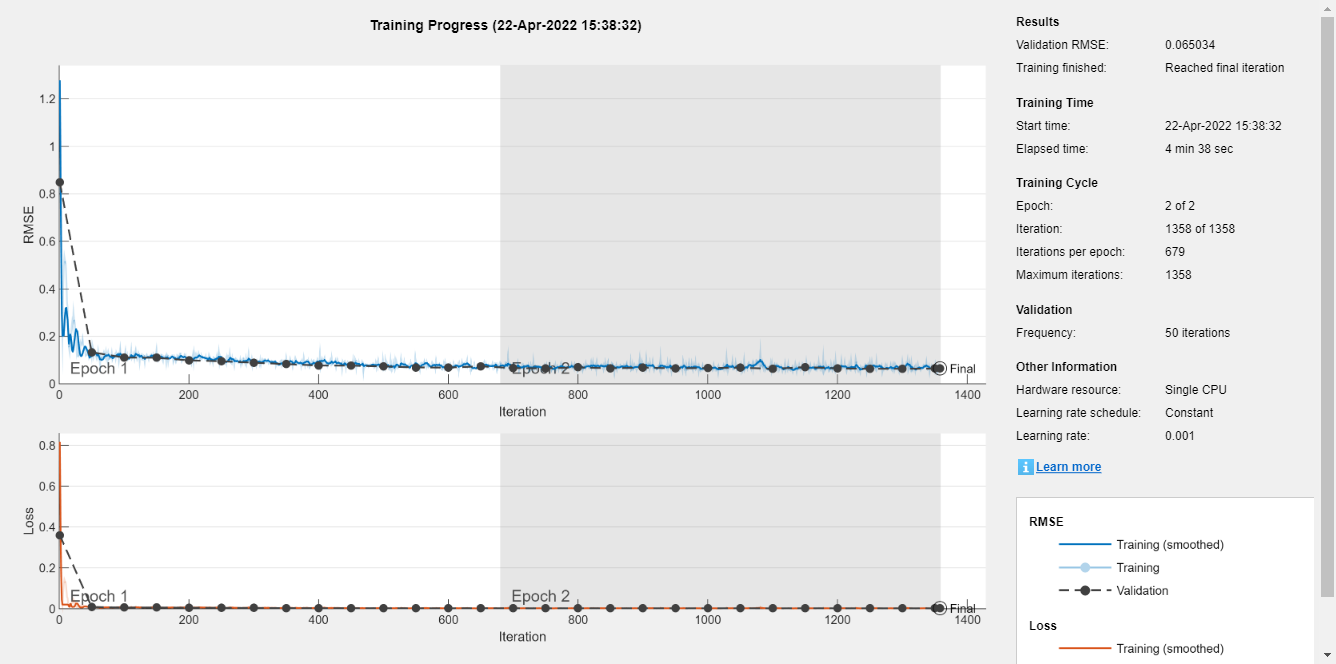

%%% 시간이 오래 걸린다.
%{ 
layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];

tic
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

toc

Elapsed time is 290.685569 seconds.


Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:10 |         0.16 |         1.84 |       0.0136 |       1.6958 |          0.0010 |
|       1 |          50 |       00:00:18 |         0.13 |         0.10 |       0.0083 |       0.0052 |          0.0010 |
|       1 |         100 |       00:00:24 |         0.10 |         0.08 |       0.0045 |       0.0032 |          0.0010 |
|       1 |         150 |       00:00:31 |         0.09 |         0.08 |       0.0040 |   

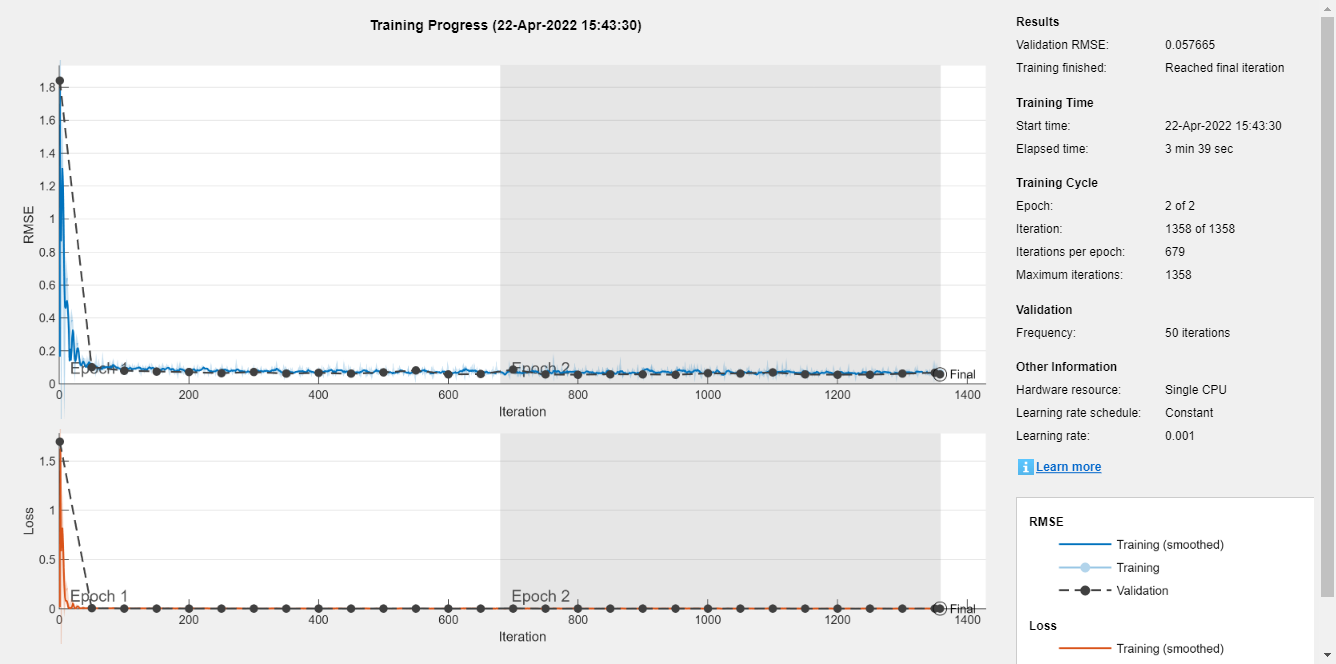


layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
tic
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

toc

Elapsed time is 238.883022 seconds.


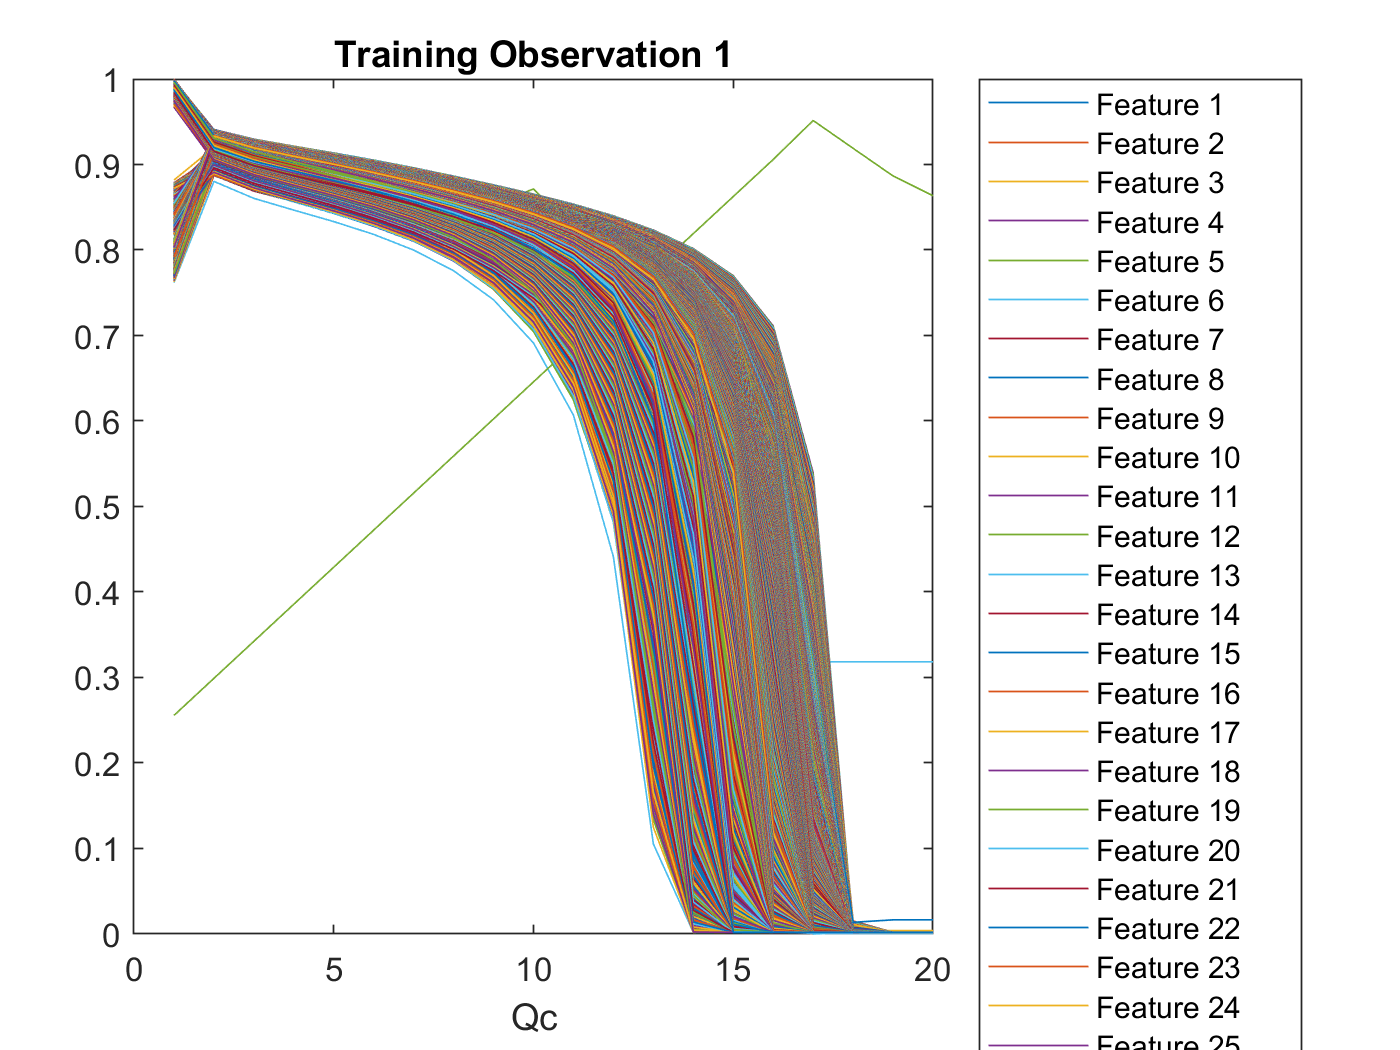


figure
plot(xnorm')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")

%}
%%%%%%%%%%%%%%

cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, cc_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d);
pCNN2_2 = predict(netCNN2_2, x_4d);
%pCNN2_3 = predict(netCNN2_3, x_4d);
%pCNN2_4 = predict(netCNN2_4, x_4d);
pCNN1_1 = predict(netCNN1_1, x_4d);




pCNN2_2_1 = 4488×1 single column vector
    0.9571
    0.9544
    0.9550
    0.9530
    0.9517
    0.9517
    0.9517
    0.9519
    0.9506
    0.9503


pCNN2_2_2 = 4488×1 single column vector
    0.9590
    0.9564
    0.9569
    0.9551
    0.9538
    0.9538
    0.9537
    0.9538
    0.9525
    0.9522


pCNN2_2_3 = 4488×1 single column vector
    0.9471
    0.9441
    0.9457
    0.9426
    0.9407
    0.9417
    0.9415
    0.9423
    0.9407
    0.9405


pCNN2_2_4 = 4488×1 single column vector
    0.9688
    0.9659
    0.9667
    0.9645
    0.9631
    0.9634
    0.9631
    0.9635
    0.9622
    0.9619


pCNN2_1_1 = 4488×1 single column vector
    0.9812
    0.9789
    0.9785
    0.9777
    0.9771
    0.9765
    0.9763
    0.9759
    0.9749
    0.9746


ytest = ynorm(tr.testInd, :)*yrate + ymin;
pCNN2_1_hat = pCNN2_1 * yrate + ymin;
pCNN2_2_hat = pCNN2_2 * yrate + ymin;
%pCNN2_3_hat = pCNN2_3 * yrate + ymin;
%pCNN2_4_hat = pCNN2_4 * yrate + ymin;
pCNN1_1_hat = pCNN1_1 * yrate + ymin;


rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

rmse_pCNN2_2_1_hat = single
0.0117

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

rmse_pCNN2_2_2_hat = single
0.0113

%rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))

rmse_pCNN2_2_3_hat = single
0.0111

%rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))

rmse_pCNN2_2_4_hat = single
0.0108

rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))

rmse_pCNN2_1_1_hat = single
0.0151

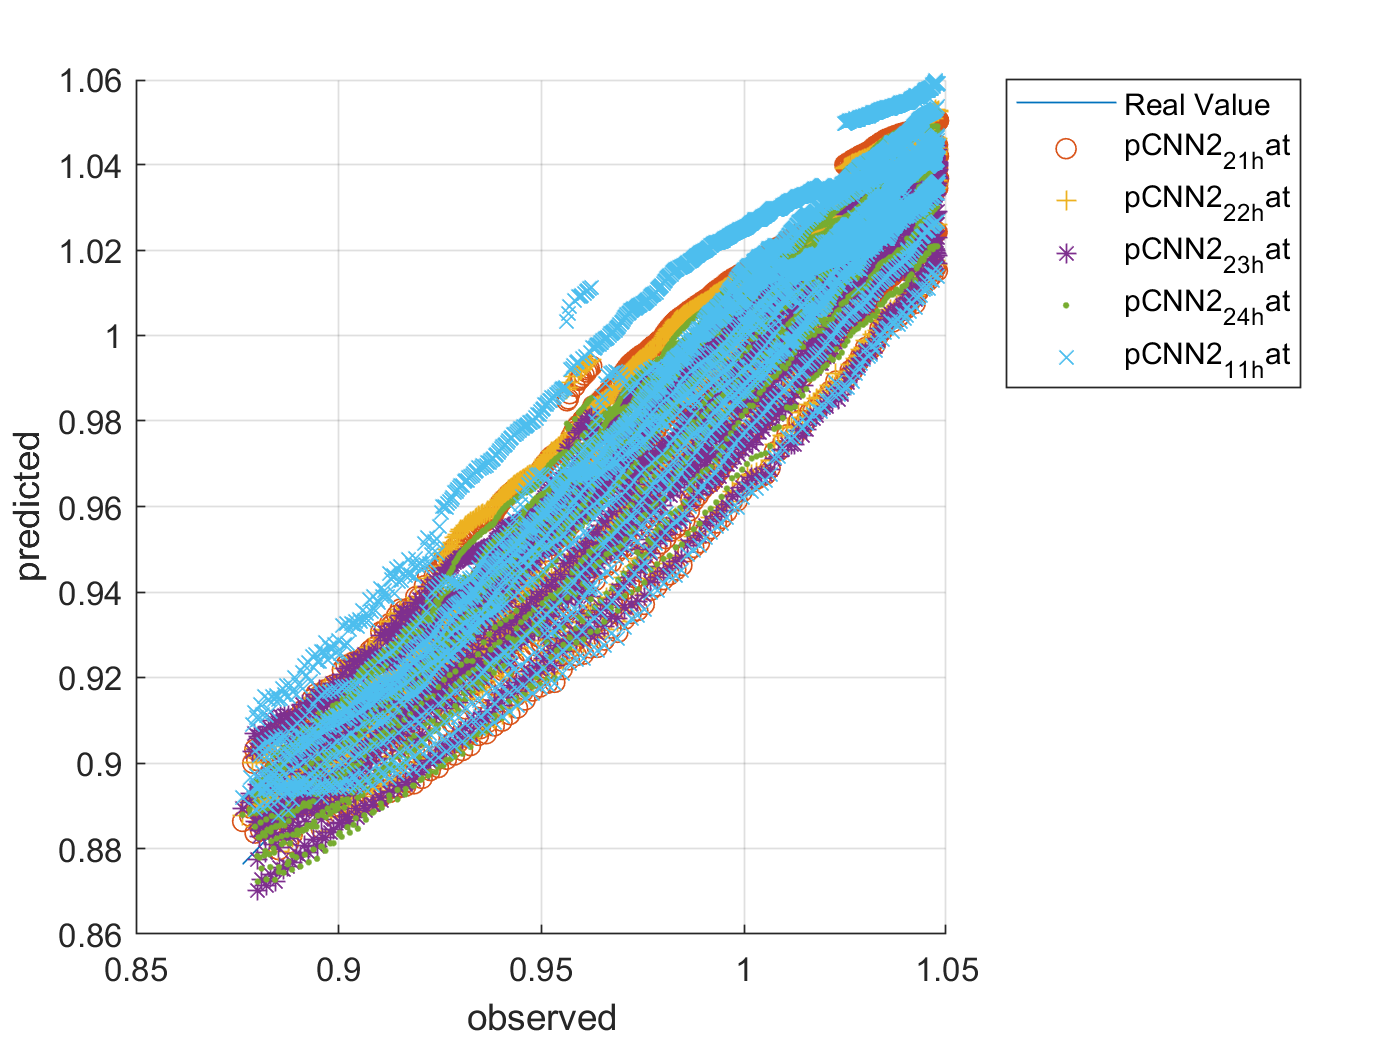




figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
%plot(ytest,pCNN2_3_hat,'*')
%plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN1_1_hat','Location','northeastoutside')




save('ryan3_model_dischargeVoltage_SOH.mat','netCNN2_1' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netCNN2_2' ,'-append')
%save('ryan3_model_dischargeVoltage_SOH.mat','netCNN2_3' ,'-append')
%save('ryan3_model_dischargeVoltage_SOH.mat','netCNN2_4' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netCNN1_1' ,'-append')

cellx_self = num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
%pCNN2_3_self = predict(netCNN2_3, x_4d_self);
%pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pCNN2_1_self_hat = pCNN2_1_self * yrate + ymin;
pCNN2_2_self_hat = pCNN2_2_self * yrate + ymin;
%pCNN2_3_self_hat = pCNN2_3_self * yrate + ymin;
%pCNN2_4_self_hat = pCNN2_4_self * yrate + ymin;
pCNN1_1_self_hat = pCNN1_1_self * yrate + ymin;



rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

rmse_pCNN2_1_self_hat = single
0.0120

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

rmse_pCNN2_2_self_hat = single
0.0119

%rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))

rmse_pCNN2_3_self_hat = single
0.0125

%rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))

rmse_pCNN2_4_self_hat = single
0.0114

rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))

rmse_pCNN1_1_self_hat = single
0.0136

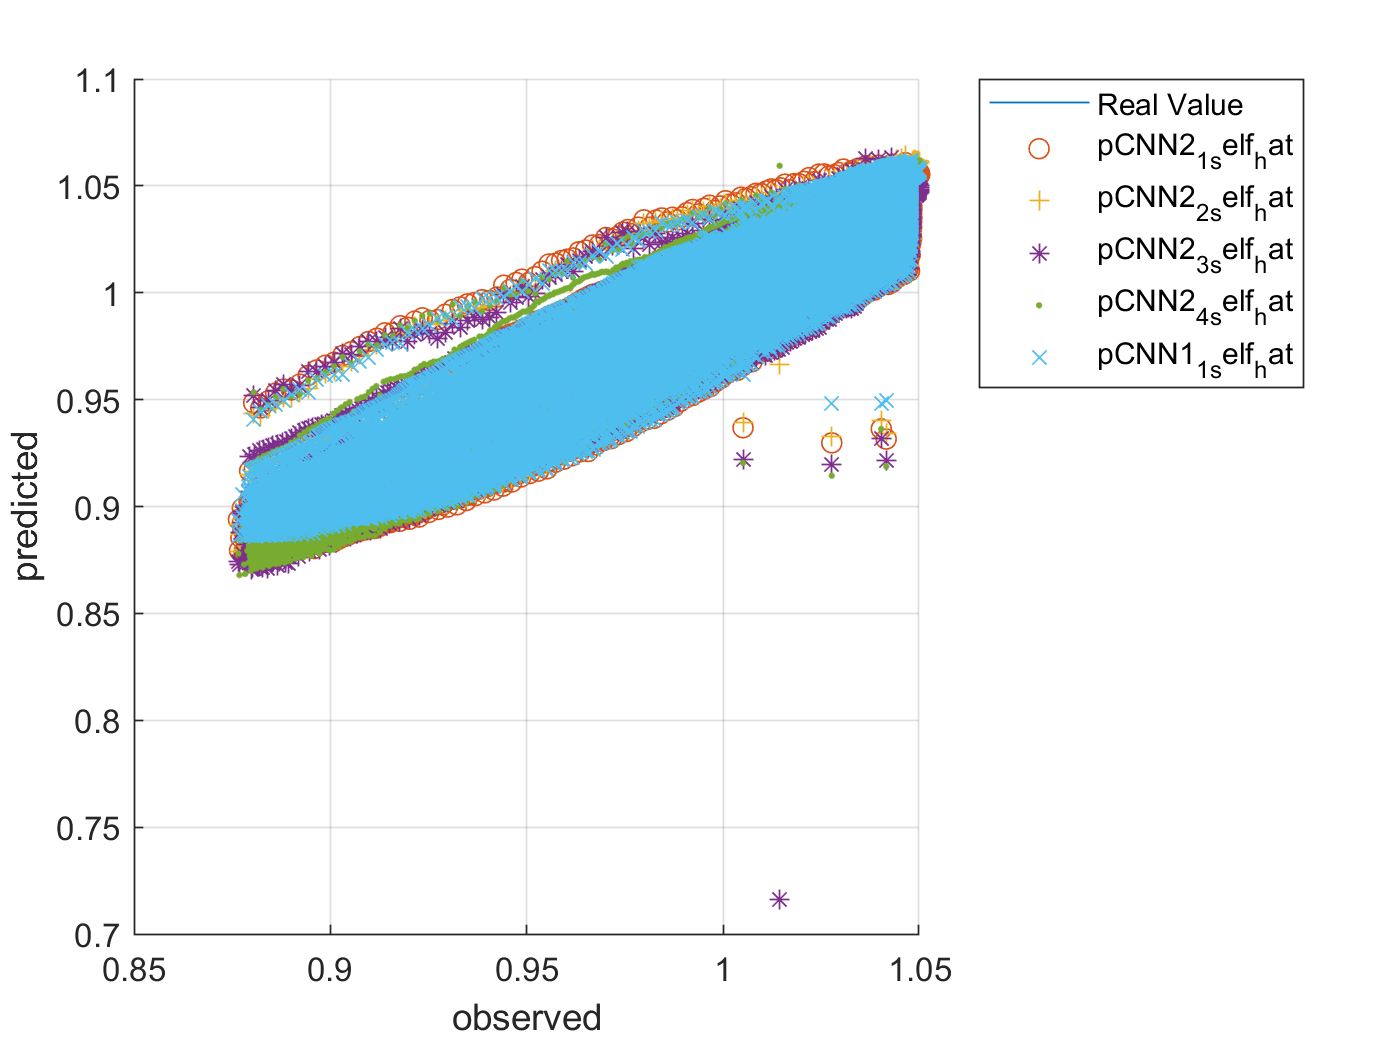




figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
%plot(ytrain_self,pCNN2_3_self_hat,'*')
%plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN1_1_self_hat','Location','northeastoutside')

# LSTM

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.63 |         0.59 |       0.1984 |       0.1760 |          0.0010 |
|       1 |          50 |       00:00:05 |         0.16 |         0.18 |       0.0123 |       0.0167 |          0.0010 |
|       1 |         100 |       00:00:07 |         0.14 |         0.14 |       0.0102 |       0.0093 |          0.0010 |
|       1 |         150 |       00:00:09 |         0.12 |         0.11 |       0.0078 |       0.0056 |          0.0010 |
|       

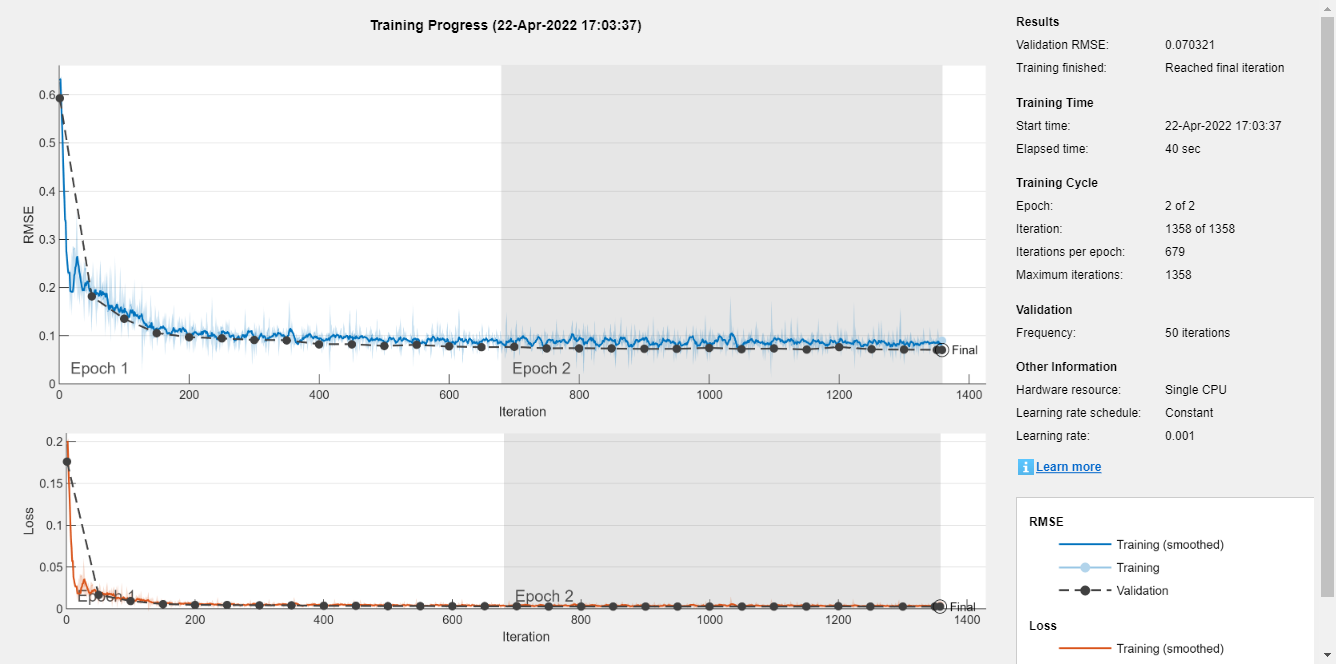

cc_input_size = 20;
numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',epoc_count, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

tic
netLSTM = trainNetwork(traincellx, traincellyB, layersLSTM, options);

toc 

Elapsed time is 48.033116 seconds.


Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         0.72 |         0.74 |       0.2579 |       0.2717 |          0.0010 |
|       1 |          50 |       00:00:07 |         0.22 |         0.20 |       0.0242 |       0.0195 |          0.0010 |
|       1 |         100 |       00:00:08 |         0.18 |         0.15 |       0.0153 |       0.0118 |          0.0010 |
|       1 |         150 |       00:00:09 |         0.15 |         0.10 |       0.0112 |       0.0052 |          0.0010 |
|       

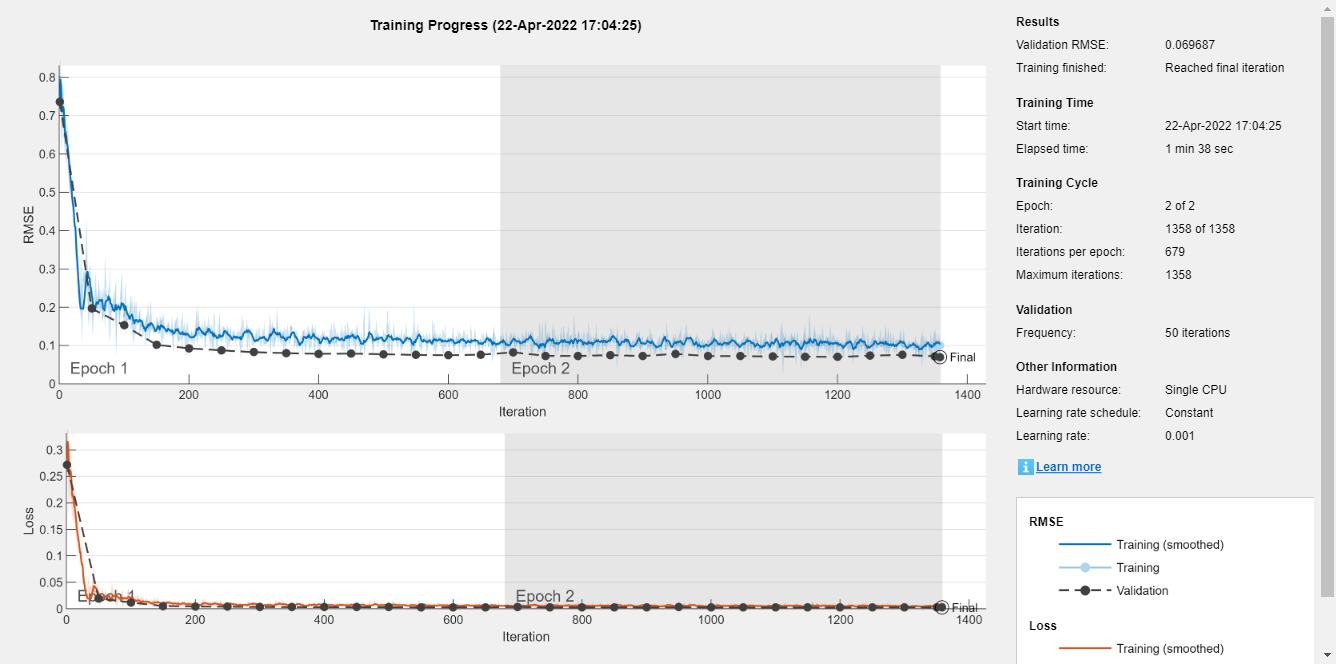


tic
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);

toc

Elapsed time is 108.424012 seconds.



pLSTM = cell2mat(predict(netLSTM, num2cell(xnorm(tr.testInd, :)', 1)));
pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm(tr.testInd, :)', 1)));
ytest = ynorm(tr.testInd, :)*yrate + ymin;
pLSTM_hat = pLSTM * yrate + ymin;
pLSTM2_hat = pLSTM2 * yrate + ymin;
rmse_pLSTM_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM_hat = single
0.0165

rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM_hat' ).^2))

rmse_pLSTM2_hat = single
0.0165

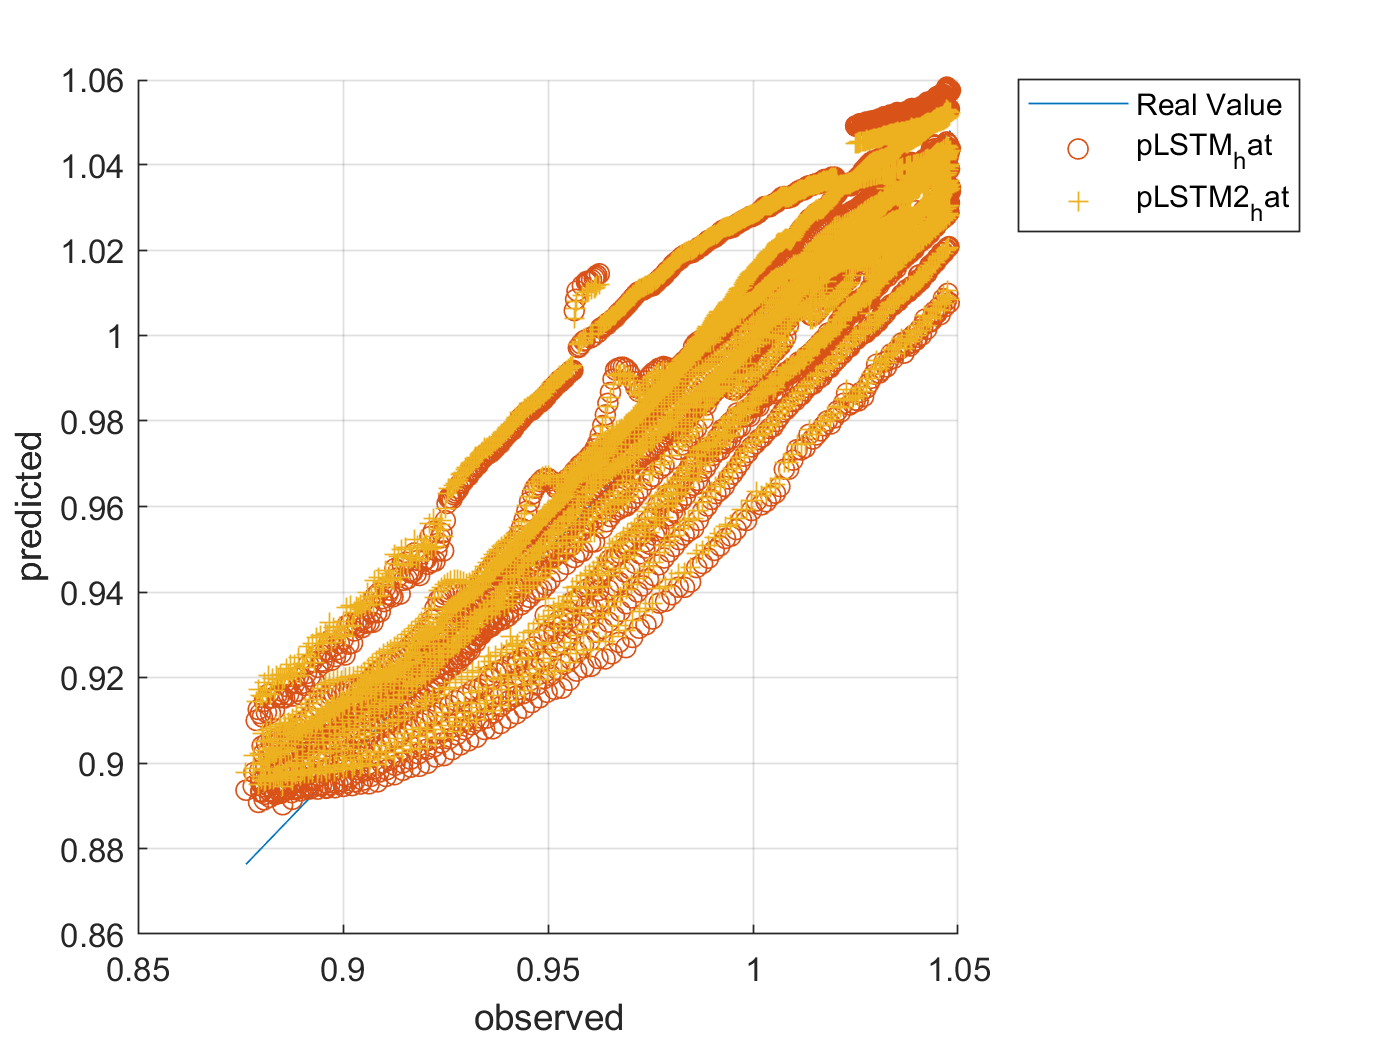



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM_hat,'o')
plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_hat', ...
        'pLSTM2_hat','Location','northeastoutside')


save('ryan3_model_dischargeVoltage_SOH.mat','netLSTM' ,'-append')
save('ryan3_model_dischargeVoltage_SOH.mat','netLSTM2' ,'-append')

pLSTM_self = cell2mat(predict(netLSTM, num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm([tr.trainInd tr.valInd], :)', 1)));
ytrain_self = ynorm([tr.trainInd tr.valInd], :)*yrate + ymin;
pLSTM_self = pLSTM_self * yrate + ymin;
pLSTM2_self = pLSTM2_self * yrate + ymin;
rmse_pLSTM_self_hat = sqrt(mean(( ytrain_self' - pLSTM_self' ).^2))

rmse_pLSTM_self_hat = single
0.0145

rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

rmse_pLSTM2_self_hat = single
0.0145

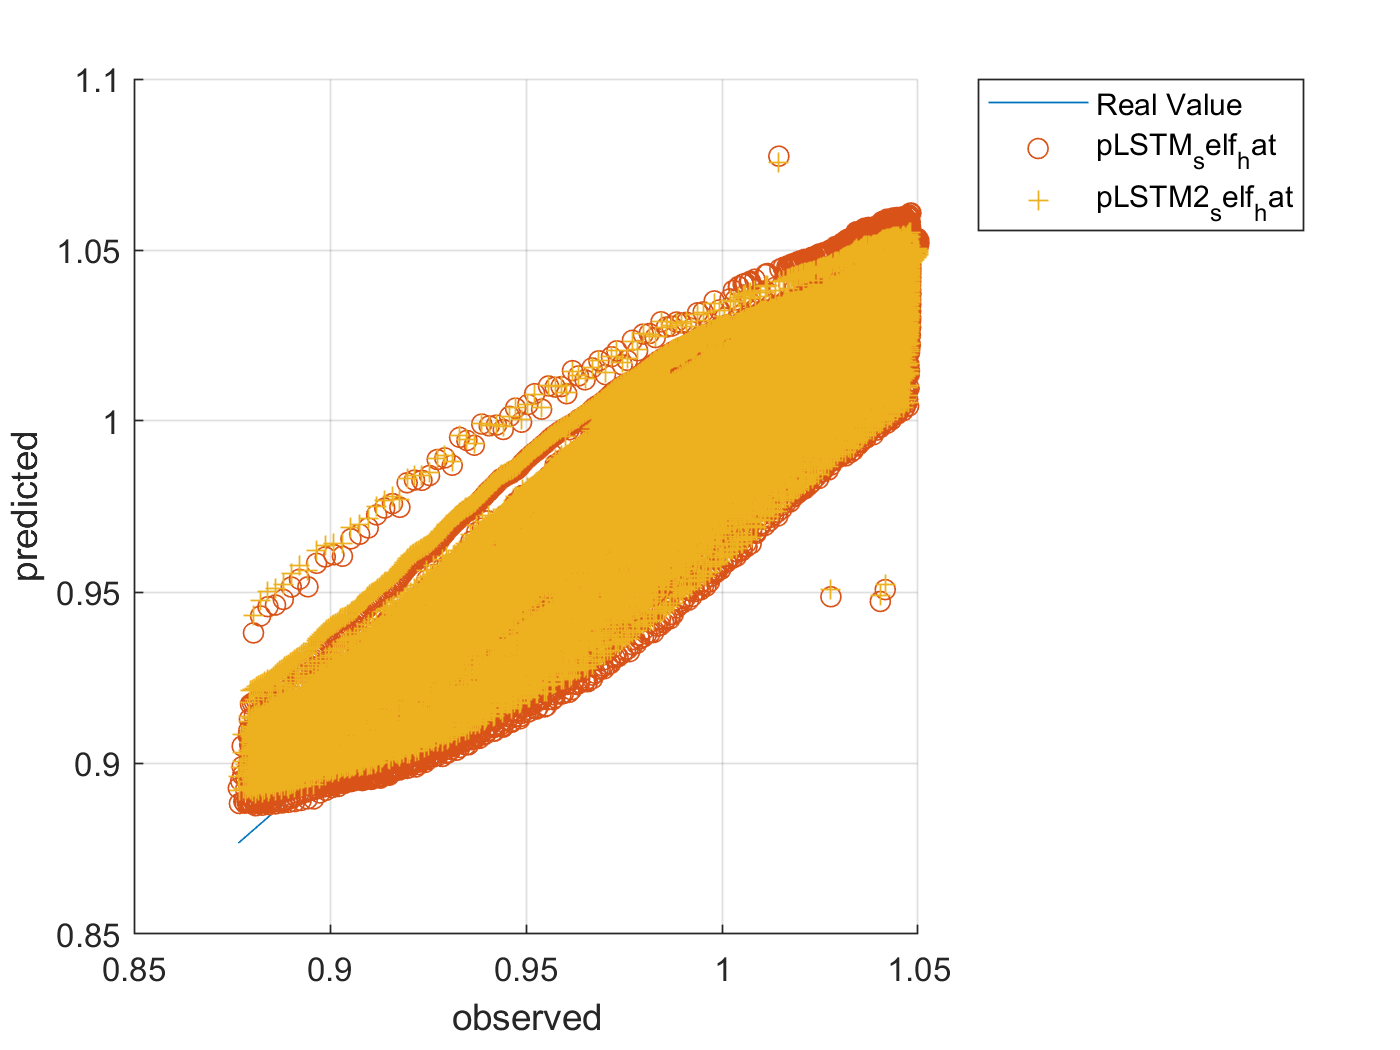


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM_self,'o')
plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')